load('E:\Data\Aurelie\best\23_12_21_17_17_08P2M_411582_230320_plane1_2023_04_05.17-57-09assemblysce6last/brainbow.mat','iscell','spks','speed','NCell','F','WinActive')
% load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_24_16_42_06P2M_411582_230320_plane1_2023_04_05.17-57-09assemblysce6last/brainbow.mat','iscell','spks','speed','NCell','F','WinActive')


% DF=double(F(iscell(:,1)>0,:));

Fluo=double(spks(iscell(:,1)>0,:));
% Fluo=normalize(Fluo,2,"center","median","scale","mad");
Fluo=normalize(Fluo,2,"center","median");
Ftemp=smoothdata(Fluo,2,"gaussian",100);
% DF=double(spks(iscell(:,1)>0,WinActive));
% DFseuil=DF;
[NCell,Nz] = size(Tr1b);
+
DF=double(spks(iscell(:,1)>0,:));
DF=DF./median(DF,2);
ws = warning('off','all');
for i=1:NCell
    p0=polyfit(1:Nz,Tr1b(i,:),3);
    Tr1b(i,:)=Tr1b(i,:)./polyval(p0,1:Nz);
end

Unrecognized function or variable 'Nz'.

warning(ws)%% preprocessing
DF = sgolayfilt(DF',3,7)';
DF(DF<0)=0;
% DF=normalize(DF,'norm');

% ws = warning('off','all');
% for i=1:NCell
%     p0=polyfit(1:Nz,DF(i,:),3);
%     DF(i,:)=DF(i,:)./polyval(p0,1:Nz);
% end
% warning(ws)%% preprocessing
% DFfilter = sgolayfilt(DF',3,7)';%was at 5
% % DF=normalize(DF,2,"medianiqr");
% % DF=normalize(DF,2,"zscore");
% DF=normalize(DF,2,"center","median","scale","mad");

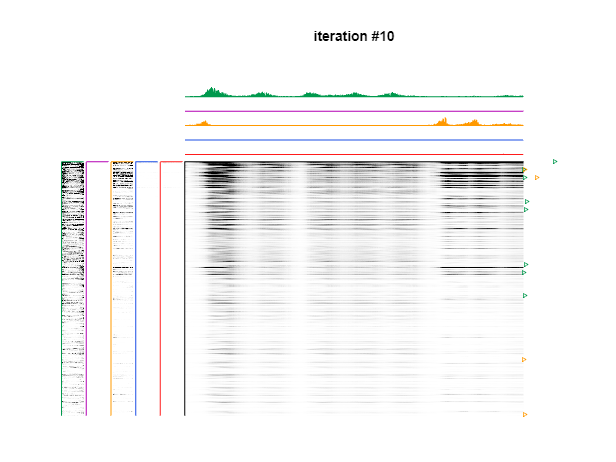

Elapsed time is 315.897772 seconds.


% K = 5;
% L = 50;
% lambda =.005;
% shg; clf
% [W, H, cost, loadings, power] = seqNMF(X, ...    % X is the data matrix
%       'K', 10, 'L', 20, 'lambda', .1, ...        % Other inputs optional
%       'W_init', W_init, 'H_init', H_init, ...
%       'showPlot', 1, 'maxiter', 20, 'tolerance', -Inf, 'shift', 1, ... 
%       'lambdaL1W', 0, 'lambdaL1H', 0, ...
%       'lambdaOrthoH', 0, 'lambdaOrthoW', 0, 'M', M)
% test=DF>0;
lambdaOrthoH = .1; % favor events-based (these can take any value, don't need to be zero and one)
lambdaOrthoW = 0;
maxiter=10 ;
K = 5;
L =100;%L=2/3  ; 400
lambda =.01;  % 0,01 to 0,001
tic 
[W, H, cost,loadings,power]= seqNMF(DF,'K',K,'L', L,...
    'lambda', lambda, 'maxiter', maxiter, 'showPlot', 1,'useWupdate',0); toc


 % figure; SimpleWHPlot(W,H); title('SeqNMF reconstruction')
% figure; SimpleWHPlot(W,H,F); title('SeqNMF factors, with raw data')

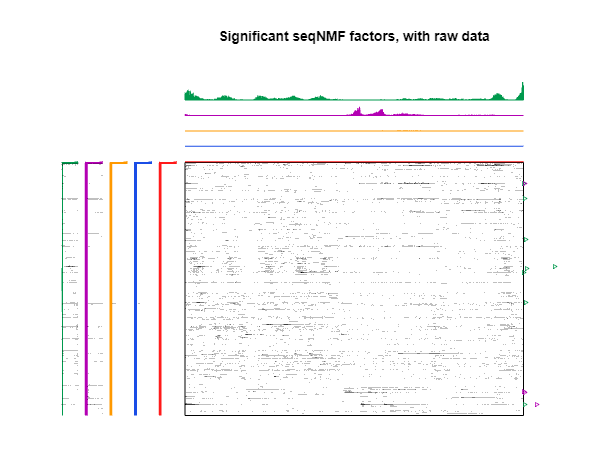

% plot, sorting neurons by latency within each factor
[max_factor, L_sort, max_sort, hybrid] = helper.ClusterByFactor(W(:,:,:),1);
indSort = hybrid(:,3);

tstart = 1;%180; % plot data starting at this timebin
figure; WHPlot(W(indSort,:,:),H(:,tstart:end),DF(indSort,tstart:end),  0)
title('Significant seqNMF factors, with raw data')

% 
% figure; WHPlot(W(indSort,:,:),H(:,tstart:end), ...
%     helper.reconstruct(W(indSort,:,:),H(:,tstart:end)),0)
% title('SeqNMF reconstruction')

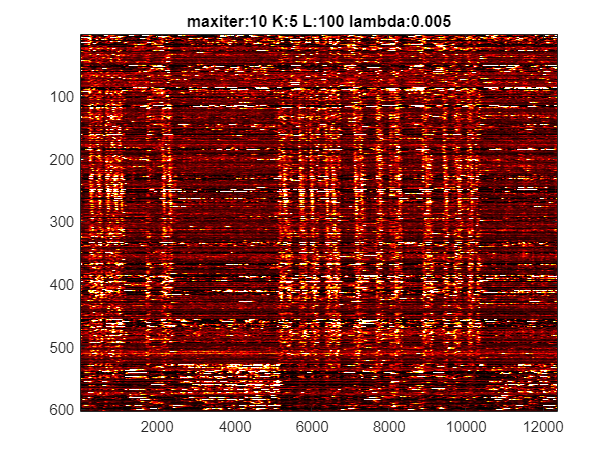

i=i+1;
figure;imagesc(Ftemp(indSort,:))
% figure;imagesc(DF(isort1,:))
% imagesc(Ftemp(isort1,WinActive))
caxis ([0 50])
colormap ("hot")
hold on
% plot (-speed*10,'Color','k')
% plot (-binary_signal*20)
% % plot (-cumulativeDistance/10)
% % hold off
% caxis ([0 10])
% text(isort2(1:100),repmat(-10,100,1),'*')
title(['maxiter:' num2str(maxiter) ' K:' num2str(K)  ' L:' num2str(L) ' lambda:' num2str(lambda)])
% ylim([-300 NCell]) 
hold off

return
% exportgraphics(gcf,[PathSave 'test' num2str(i) '.png'],'Resolution',300)

%% Procedure for choosing K
tic
Ws = {};
Hs = {};
numfits = 3; %number of fits to compare
for k = 1:20
    display(sprintf('running seqNMF with K = %i',k))
    for ii = 1:numfits
        [Ws{ii,k},Hs{ii,k}] = seqNMF(DF,'K',k, 'L', L,'lambda', 0,'maxiter',30,'showplot',0); 
        % note that max iter set low (30iter) for speed in demo (not recommended in practice)
    end
    inds = nchoosek(1:numfits,2);
    parfor i = 1:size(inds,1) % consider using parfor for larger numfits
            Diss(i,k) = helper.DISSX(Hs{inds(i,1),k},Ws{inds(i,1),k},Hs{inds(i,2),k},Ws{inds(i,2),k});
    end
    
end

figure,
plot(1:11,Diss,'ko'), hold on
h1 = plot(1:11,median(Diss,1),'k-','linewidth',2);
h2 = plot([3,3],[0,0.5],'r--');
legend([h1 h2], {'median Diss','true K'})
xlabel('K')
ylabel('Diss')